% Closed Loop systems

%Continous

%Pitch Control Loop
sys_Pitch = ss(PitchSystem.A-PitchSystem.B*Kp,PitchSystem.B*Kp(1),PitchSystem.C,PitchSystem.D);
tf(sys_Pitch)

ans =
 
        50
  ---------------
  s^2 + 10 s + 50
 
Continuous-time transfer function.



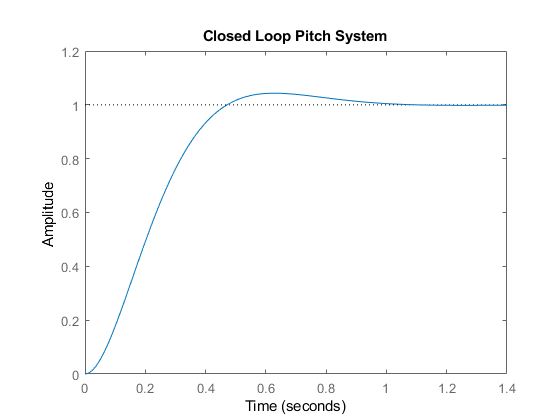

figure()
step(sys_Pitch)
title('Closed Loop Pitch System')

sys_Roll = ss(RollSystem.A-RollSystem.B*Kr,RollSystem.B*Kr(1),RollSystem.C,RollSystem.D);
tf(sys_Roll)

ans =
 
        50
  ---------------
  s^2 + 10 s + 50
 
Continuous-time transfer function.



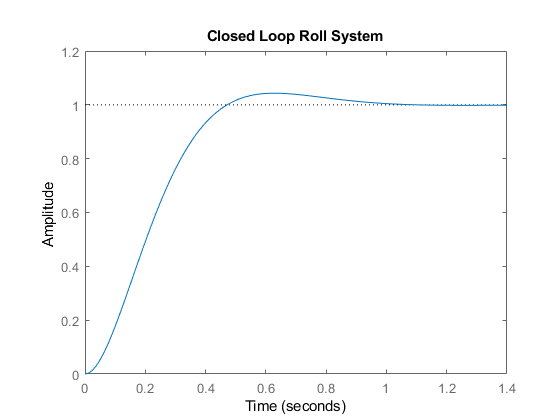

figure()
step(sys_Roll) 
title('Closed Loop Roll System')

sys_Yaw = ss(YawSystem.A-YawSystem.B*Kyawc,YawSystem.B*Kyawc(1),YawSystem.C,YawSystem.D);
tf(sys_Yaw)

ans =
 
        29
  ---------------
  s^2 + 10 s + 29
 
Continuous-time transfer function.



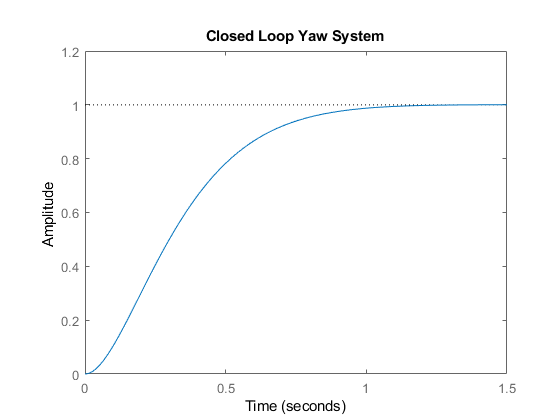

figure()
step(sys_Yaw) 
title('Closed Loop Yaw System')

%XDot Model

%Approx - Desired Pitch angle is achieved instantly
TFxc = Kx*feedback(tf(XDotSystem),Kx)

TFxc =
 
    3.5
  -------
  s + 3.5
 
Continuous-time transfer function.



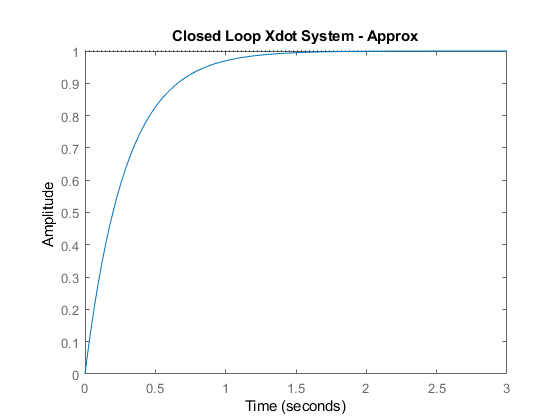

figure()
step(TFxc)
title('Closed Loop Xdot System - Approx')

%Actual
TFxc_withPitchLoop = Kx*feedback(tf(sys_Pitch)*tf(XDotSystem),Kx)

TFxc_withPitchLoop =
 
             175
  -------------------------
  s^3 + 10 s^2 + 50 s + 175
 
Continuous-time transfer function.



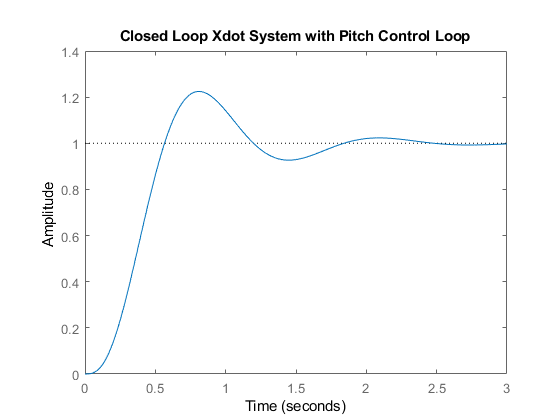

figure()
step(TFxc_withPitchLoop)
title('Closed Loop Xdot System with Pitch Control Loop')

%Ydot Model

%Approx - Desired Roll angle is achieved instantly
TFyc = Ky*feedback(tf(YDotSystem),Ky)

TFyc =
 
    3.5
  -------
  s + 3.5
 
Continuous-time transfer function.



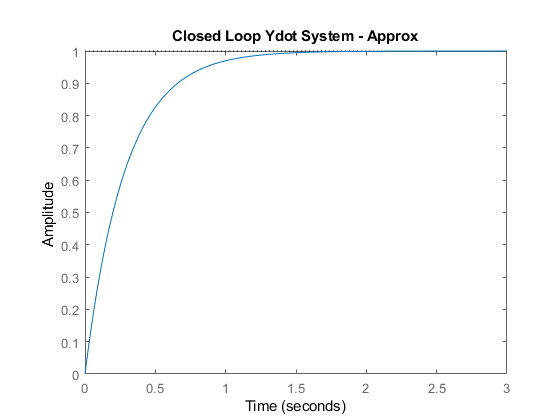

figure()
step(TFyc)
title('Closed Loop Ydot System - Approx')


%Actual
TFyc_withRollLoop = Ky*feedback(tf(sys_Roll)*tf(YDotSystem),Ky)

TFyc_withRollLoop =
 
             175
  -------------------------
  s^3 + 10 s^2 + 50 s + 175
 
Continuous-time transfer function.



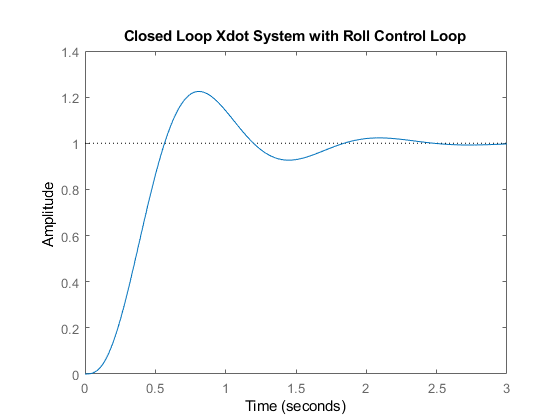

figure()
step(TFyc_withRollLoop)
title('Closed Loop Ydot System with Roll Control Loop')


%Discretized
sys_Pitch_d = ss(PitchSystem_d.A-PitchSystem_d.B*Kp_d,PitchSystem_d.B*Kp_d(1),PitchSystem_d.C,PitchSystem_d.D,Ts);
tf(sys_Pitch_d)

ans =
 
  0.009048 z + 0.009048
  ----------------------
  z^2 - 1.801 z + 0.8187
 
Sample time: 0.02 seconds
Discrete-time transfer function.



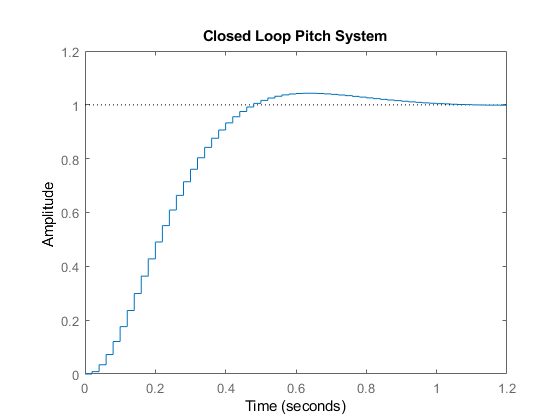

figure()
step(sys_Pitch_d) 
title('Closed Loop Pitch System')


sys_Roll_d = ss(RollSystem_d.A-RollSystem_d.B*Kr_d,RollSystem_d.B*Kr_d(1),RollSystem_d.C,RollSystem_d.D,Ts);
tf(sys_Roll_d)

ans =
 
  0.009048 z + 0.009048
  ----------------------
  z^2 - 1.801 z + 0.8187
 
Sample time: 0.02 seconds
Discrete-time transfer function.



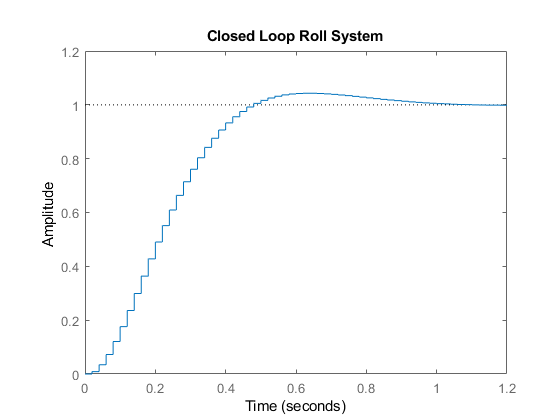

figure()
step(sys_Roll_d) 
title('Closed Loop Roll System')


sys_Yaw_d = ss(YawSystem_d.A-YawSystem_d.B*Kyaw_d,YawSystem_d.B*Kyaw_d(1),YawSystem_d.C,YawSystem_d.D,Ts);
tf(sys_Yaw_d)

ans =
 
  0.005252 z + 0.005252
  ----------------------
  z^2 - 1.808 z + 0.8187
 
Sample time: 0.02 seconds
Discrete-time transfer function.



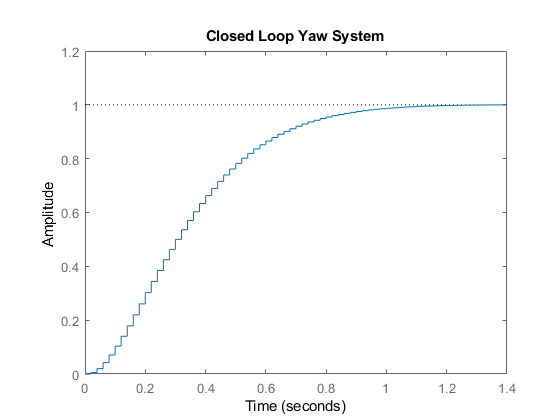

figure()
step(sys_Yaw_d) 
title('Closed Loop Yaw System')


%XDot System

% Approx - Pitch Angle achieved instantly
TFxc_d = Kx_d*feedback(tf(XSystem_d),Kx_d)

TFxc_d =
 
   0.06761
  ----------
  z - 0.9324
 
Sample time: 0.02 seconds
Discrete-time transfer function.



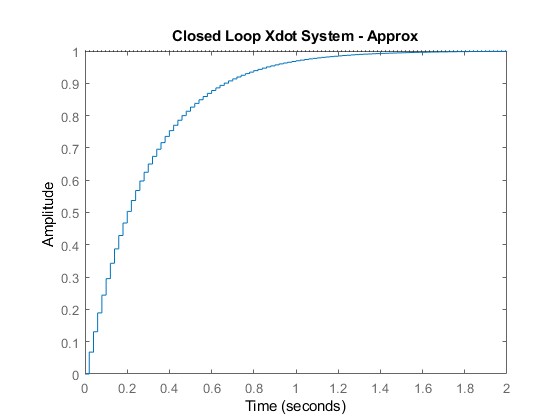

figure()
step(TFxc_d)
title('Closed Loop Xdot System - Approx')


% Actual - 
TFxc_d_withPitchLoop = Kx_d*feedback(tf(sys_Pitch_d)*tf(XSystem_d),Kx_d)

TFxc_d_withPitchLoop =
 
       0.0006117 z + 0.0006117
  ---------------------------------
  z^3 - 2.801 z^2 + 2.62 z - 0.8181
 
Sample time: 0.02 seconds
Discrete-time transfer function.



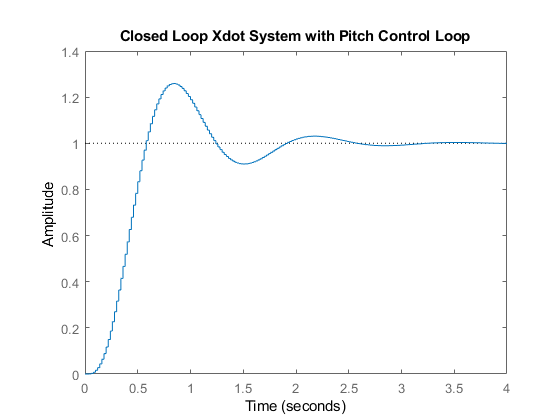

figure()
step(TFxc_d_withPitchLoop)
title('Closed Loop Xdot System with Pitch Control Loop')


%YDot System

%Approx 
TFyc_d = Ky_d*feedback(tf(YSystem_d),Ky_d)

TFyc_d =
 
   0.06761
  ----------
  z - 0.9324
 
Sample time: 0.02 seconds
Discrete-time transfer function.



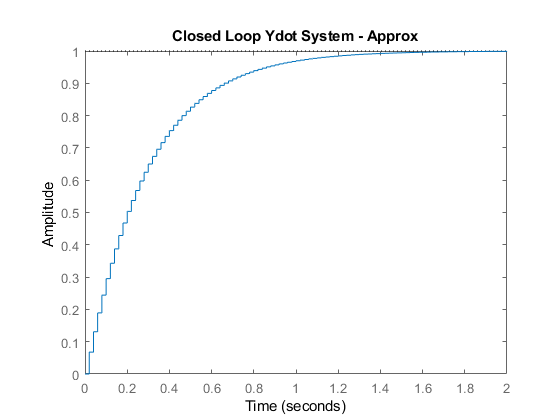

figure()
step(TFyc_d)
title('Closed Loop Ydot System - Approx')


%Actual
TFyc_d_withPitchLoop = Ky_d*feedback(tf(sys_Roll_d)*tf(YSystem_d),Ky_d)

TFyc_d_withPitchLoop =
 
       0.0006117 z + 0.0006117
  ---------------------------------
  z^3 - 2.801 z^2 + 2.62 z - 0.8181
 
Sample time: 0.02 seconds
Discrete-time transfer function.



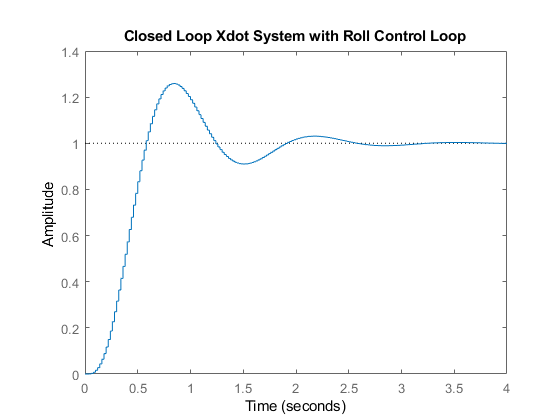

figure()
step(TFyc_d_withPitchLoop)
title('Closed Loop Ydot System with Roll Control Loop')